**Name : Krish Singh**

**Roll: AID25072**

**AID Semester 2**

## **LAB EXCERCISE 6**

**1. Generate a sample of 2000 numbers from a standard normal population using Box-Muller’s method and draw the histogram. **

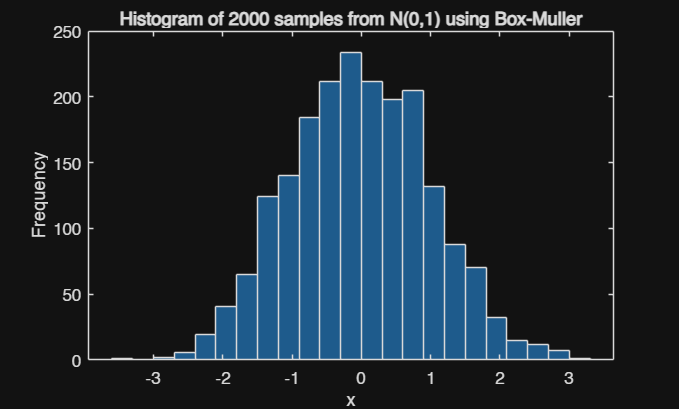

u1=rand(1000,1);
u2=rand(1000,1);
r=-2*log(u1);
theta=2*pi*u2;
x1=sqrt(r).*cos(theta);
x2=sqrt(r).*sin(theta);
x=[x1;x2];
histogram(x);
title('Histogram of 2000 samples from N(0,1) using Box-Muller');
xlabel('x');
ylabel('Frequency')

2. Generate a sample of 100 normally distributed numbers with mean 55 and standard deviation 10 using Box-Muller’s formula and draw the histogram. 

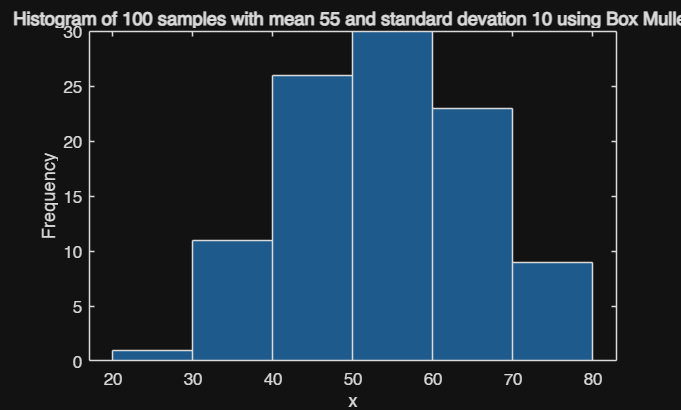

mean=55;
std=10;
u1=rand(50,1);
u2=rand(50,1);
r=-2*log(u1);
theta=2*pi*u2;
x1=mean+std*(sqrt(r).*cos(theta));
x2=mean+std*(sqrt(r).*sin(theta));
x=[x1;x2];
histogram(x)
title("Histogram of 100 samples with mean 55 and standard devation 10 using Box Muller");
xlabel('x')
ylabel('Frequency')

3. Generate 1200 numbers from a standard normal population, directly using the MATLAB command, ‘randn’. 

(a) Draw a histogram and check if the curve is bell shape.

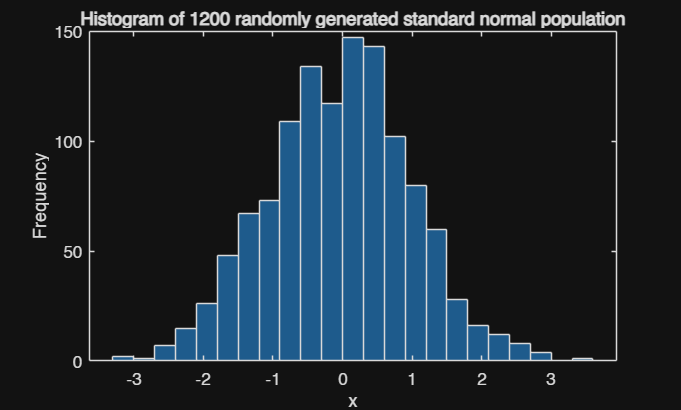

x=randn(1200,1);
histogram(x);
title('Histogram of 1200 randomly generated standard normal population')
xlabel('x')
ylabel('Frequency')

(b) Find the mean and variance of the sample drawn and compare it with the mean and variance of the population. 

samplemean=mean(x)

samplemean = -0.0387

variance=var(x)

variance = 1.0385

4. Generate 500 numbers from a normal population with mean 300 and variance 50, using ‘randn’ command. 

(a) Draw a histogram with 20 bins. 

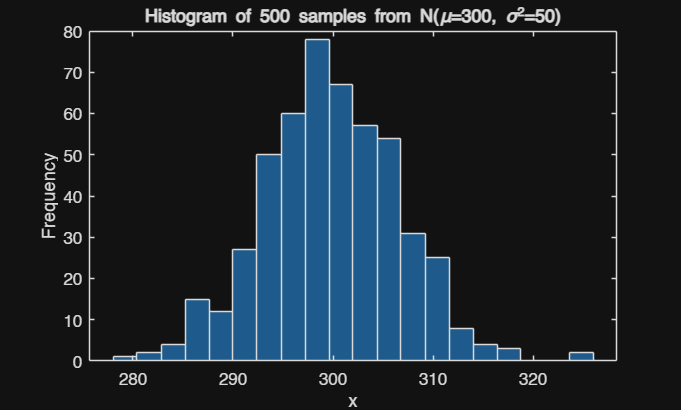

meanv=300;
std=sqrt(50);
u=randn(500,1);
x=meanv+std*u;
histogram(x,20);
title('Histogram of 500 samples from N(\mu=300, \sigma^2=50)');
xlabel('x');
ylabel('Frequency');

(b) Find the mean and variance of the sample and compare with that of the population . 

clear mean;
meanp=mean(x)

meanp = 299.8612

variance=var(x)

variance = 45.4828

(c) Plot the pdf of the normal distribution. 

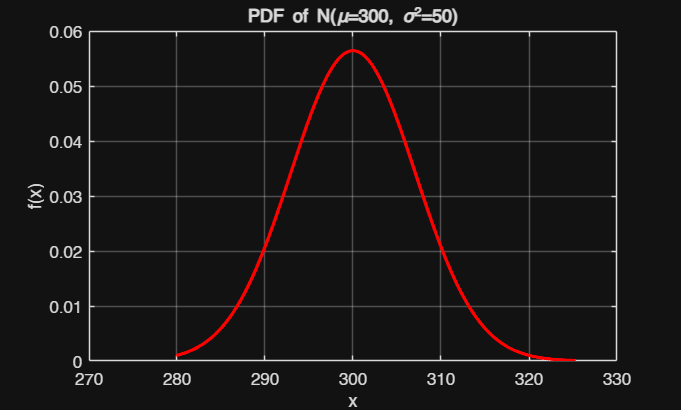

x_range=linspace(min(x),max(x),1000);
pdfval=pdf('norm',x_range,meanv,std);
plot(x_range, pdfval, 'r', 'LineWidth', 2);
title('PDF of N(\mu=300, \sigma^2=50)');
xlabel('x');
ylabel('f(x)');
grid on;

5. Evaluate the mean and variance of the samples generated in the previous 2 questions and compare it with the actual mean and variance of the given distribution. 

% Q3 - 1200 samples from N(0,1)
q3 = randn(1200,1);

% Q4 - 500 samples from N(300,50)
mu = 300;
sigma = sqrt(50);
q4 = mu + sigma*randn(500,1);

% Mean and variance of both samples
mean_q3 = mean(q3)

mean_q3 = -0.0263

var_q3 = var(q3)

var_q3 = 1.0045

mean_q4 = mean(q4)

mean_q4 = 299.7325

var_q4 = var(q4)

var_q4 = 49.1891

6. Generate a sample of size 1000 from a population with probability density, f(x)=3x^2, 0<x<1 and draw the histogram for the sample with 20 bins. Also find the sample mean, sample variance of the generated sample and compare with the actual mean and variance of the population. (Hint: Use CDF in the way it was used to find the formula to generate sample for exponential distribution) 